# Camera Pose Estimation Using AprilTag Markers for NeRF

clear; close all force; clc; rng('default');
prj = currentProject;
rootFolder = prj.RootFolder;

### Step 1: Generate the pattern

#### Download and prepare tag images 

Pre-generated tags for all the supported families can be downloaded from [here](https://github.com/AprilRobotics/apriltag-imgs) using a web browser or by running the following code:

downloadURL  = 'https://github.com/AprilRobotics/apriltag-imgs/archive/master.zip';
dataFolder   = fullfile(char(rootFolder),'apriltag-imgs', filesep);
options      = weboptions('Timeout', Inf);
zipFileName  = [dataFolder, 'apriltag-imgs-master.zip'];
folderExists = exist(dataFolder, 'dir');

% Create a folder in a temporary directory to save the downloaded file
if ~folderExists
    mkdir(dataFolder);
    disp('Downloading apriltag-imgs-master.zip (60.1 MB)...')
    websave(zipFileName, downloadURL, options);

    % Extract contents of the downloaded file
    disp('Extracting apriltag-imgs-master.zip...')
    unzip(zipFileName, dataFolder);
end

The example uses the **tag36h11 **family, which provides a reasonable trade-off between detection performance and robustness to false-positive detections.

% Set the properties of the calibration pattern.
tagArrangement = [5,8];
tagFamily = 'tag36h11';

% Generate the calibration pattern using AprilTags.
tagImageFolder = [dataFolder 'apriltag-imgs-master/' tagFamily];
imdsTags = imageDatastore(tagImageFolder);
figure;
calibPattern = helperGenerateAprilTagPattern(imdsTags, tagArrangement, tagFamily);
imwrite(calibPattern,"calibPattern.png");

Using the `readAprilTag` function on this pattern results in detections with the corner locations of the individual tags grouped together.

% Read and localize the tags in the calibration pattern.
[tagIdsOrg, tagLocs] = readAprilTag(calibPattern, tagFamily);

% Display corner locations.
figure; imshow(calibPattern); hold on
plot(squeeze(tagLocs(:,1,:)), squeeze(tagLocs(:,2,:)),'o','MarkerSize',15)
text(reshape(tagLocs(:,1,:),[],1),reshape(tagLocs(:,2,:),[],1),string(1:numel(tagLocs(:,2,:))));

### Step 2: Detect and localize the AprilTags in a video

The [helperDetectAprilTagCorners](matlab:help('helperDetectAprilTagCorners')) function, included at the end of the example, is used to detect and localize the tags from the captured images and arrange them in a checkerboard fashion to be used as key points in the calibration procedure.

videoFile = fullfile("x_pipe.mp4");
tagSize = 0.019; % in meters 
maxFrames = 200;

[~,fname,~] = fileparts(videoFile);
datasetPath = fullfile("data",fname);
imagePath = fullfile(datasetPath,"image");

if exist(datasetPath,"dir")
    rmdir(datasetPath,"s");
end
[~,~,~] = mkdir(datasetPath);
[~,~,~] = mkdir(imagePath);

videoReader = VideoReader(videoFile);
videoPlayer = vision.DeployableVideoPlayer;
if ispc
    videoWriter = vision.VideoFileWriter(fullfile(datasetPath,"keyframes.mp4"),...
        'FileFormat','MPEG4','FrameRate',videoReader.FrameRate,'Quality',95);
else
    videoWriter = vision.VideoFileWriter(fullfile(datasetPath,"keyframes.avi"),...
        'FileFormat','AVI','FrameRate',videoReader.FrameRate);
end
cmaps = im2uint8(lines(numel(tagIdsOrg)));

videoIndex = 1;
prevId = [];
prevLoc = [];
for k = 1:videoReader.NumFrames
    % Read an image
    I = read(videoReader,k);
    
    [id,loc] = readAprilTag(I,tagFamily);
    if isempty(prevId)
        isKeyFrame = true;
    else
        [C,ia,ib] = intersect(id,prevId);
        if numel(C) > 4
            meanDist = mean(sqrt(sum((loc(:,:,ia) - prevLoc(:,:,ib)).^2,2)),"all");
            isKeyFrame = meanDist > 200;
        elseif numel(id) > 4
            isKeyFrame = true;
        else
            isKeyFrame = false;
        end
    end

    scaleFactor = 0.5;
    Iout = imresize(I,scaleFactor);
    if ~isempty(loc)
        markerPos = reshape(permute(loc,[2,1,3]),8,[])' * scaleFactor;
        [~,ind] = ismember(id,tagIdsOrg);
        colors = cmaps(ind,:);
        Iout = insertShape(Iout,"FilledPolygon", markerPos, Color=colors,Opacity=0.5,LineWidth=5);
        points = reshape(markerPos',2,[])';
        Iout = insertShape(Iout,'filledcircle',[points, 3*ones(size(points,1),1)],...
            'Color','green','Opacity',0.9);

    end
    Iout = insertText(Iout,[1,1],"Num of markers:"+string(numel(id)));
    Iout = insertText(Iout,[1,50],"Num of key frames:"+string(videoIndex)+"/("+maxFrames+")");
    videoPlayer(Iout);
    videoWriter(Iout);

    if isKeyFrame
        imwrite(I,fullfile(imagePath,"image_"+num2str(videoIndex,"%04d")+".png"));
        videoIndex = videoIndex + 1;
        prevId = id;
        prevLoc = loc;
        if videoIndex > maxFrames
            break;
        end
    end
end
release(videoWriter);

% Create an imageDatastore object to store the captured images.
imdsCalib = imageDatastore(imagePath);

% Detect the calibration pattern from the images.
[imagePoints, boardSize, imagesUsed] = helperDetectAprilTagCorners(imdsCalib, tagArrangement, tagIdsOrg, tagFamily);

### Step 3: Generate world points for the calibration pattern

The generated AprilTag pattern is such that the tags are located in a checkerboard fashion, and so the world coordinates for the corresponding image coordinates determined above (in `imagePoints`) can be obtained using the [`generateCheckerboardPoints`](docid:vision_ref#btykex9-1) function.

Here, the size of the square is replaced by the size of the tag and the size of the board is obtained from the previous step. Measure the tag size between the outer black edges of one side of the tag.

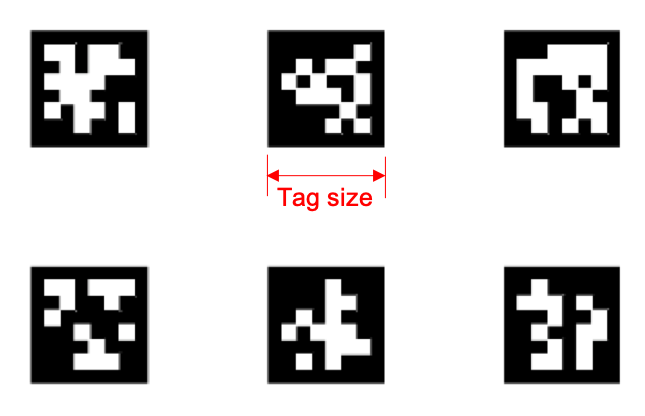

% Generate world point coordinates for the pattern.
worldPointsAll = generateCheckerboardPoints(boardSize, tagSize);
worldCenter = mean(worldPointsAll,1);
worldPointsAll = worldPointsAll - worldCenter;
worldPointsAll = reshape(permute(reshape(worldPointsAll,2,tagArrangement(1),2,tagArrangement(2),2),[1 3 5 2 4]),4,2,[]);
worldPointsAll = permute(worldPointsAll,[1 3 2]);
worldPoints = worldPointsAll([2 4 3 1],:,:);
figure, ax = plot(worldPoints(:,:,1),worldPoints(:,:,2),'o');
axis ij
hold on;
text(reshape(worldPoints(:,:,1),1,[]),reshape(worldPoints(:,:,2),1,[]),string(1:(numel(worldPoints)/2)));
xlabel('X'); ylabel('Y'); axis equal;

### Step 4: Estimate camera parameters and poses

% Determine the size of the images.
I = readimage(imdsCalib, 1);

figure;
imshow(I)
imageSize = [size(I,1), size(I,2)];

% Estimate the camera parameters and poses
cameraParams = estimateCameraParameters(imagePoints, reshape(worldPoints, [], 2),...
    "WorldUnits","m","ImageSize",imageSize);


Visualize the accuracy of the calibration and the extrinsic camera parameters showing the planes of the calibration pattern in the captured images.

% Display the reprojection errors.
figure
showReprojectionErrors(cameraParams)

% Display the extrinsics.
figure
showExtrinsics(cameraParams,"PatternCentric")

Inspect the locations of the detected image points and the reprojected points obtained using the estimated camera parameters.

% Read a calibration image.
idxUsed = find(imagesUsed);
I = readimage(imdsCalib, idxUsed(1));

% Insert markers for the detected and reprojected points.
imagePointsValid = imagePoints(:,:,idxUsed(1));
imagePointsValid(any(isnan(imagePointsValid),2),:) = [];
I = insertShape(I,'filledcircle',[imagePointsValid, 10*ones(size(imagePointsValid,1),1)],...
    'Color','green','Opacity',0.9);
reproPointsValid = cameraParams.ReprojectedPoints(:,:,idxUsed(1));
reproPointsValid(any(isnan(reproPointsValid),2),:) = [];
I = insertShape(I,'filledcircle',[reproPointsValid, 5*ones(size(reproPointsValid,1),1)],...
    'Color','red','Opacity',0.9);

% Display the image.
figure
imshow(I)
camPoses = cameraParams.PatternExtrinsics;
camPoses = arrayfun(@(x) rigidtform3d(x.R,x.Translation).invert,camPoses);

save(fullfile(datasetPath,"camPoses"),"camPoses");
intrinsics = cameraParams.Intrinsics;
save(fullfile(datasetPath,"intrinsics"),"intrinsics");

function calibPattern = helperGenerateAprilTagPattern(imdsTags,tagArragement,tagFamily)

numTags = tagArragement(1)*tagArragement(2);
tagIds = zeros(1,numTags);

% Read the first image.
I = readimage(imdsTags,3);
Igray = im2gray(I);

% Scale up the thumbnail tag image.
Ires = imresize(Igray,15,"nearest");

% Detect the tag ID and location (in image coordinates).
[tagIds(1), tagLoc] = readAprilTag(Ires,tagFamily);

% Pad image with white boundaries (ensures the tags replace the black
% portions of the checkerboard).
tagSize = round(max(tagLoc(:,2)) - min(tagLoc(:,2)));
padSize = round(tagSize/2 - (size(Ires,2) - tagSize)/2);
Ires = padarray(Ires,[padSize,padSize],255);

% Initialize tagImages array to hold the scaled tags.
tagImages = zeros(size(Ires,1),size(Ires,2),numTags);
tagImages(:,:,1) = Ires;

for idx = 2:numTags
   
    I = readimage(imdsTags,idx + 2);
    Igray = im2gray(I);
    Ires = imresize(Igray,15,"nearest");
    Ires = padarray(Ires,[padSize,padSize],255);
    
    tagIds(idx) = readAprilTag(Ires,tagFamily);
    
    % Store the tag images.
    tagImages(:,:,idx) = Ires;
     
end

% Sort the tag images based on their IDs.
[~, sortIdx] = sort(tagIds);
tagImages = tagImages(:,:,sortIdx);

% Reshape the tag images to ensure that they appear in column-major order
% (montage function places image in row-major order).
columnMajIdx = reshape(1:numTags,tagArragement)';
tagImages = tagImages(:,:,columnMajIdx(:));

% Create the pattern using 'montage'.
imgData = montage(tagImages,Size=tagArragement);
calibPattern = imgData.CData;

end

function [imagePoints, boardSize, imagesUsed] = helperDetectAprilTagCorners(imdsCalib, tagArrangement, tagIdsOrg, tagFamily)
%   Copyright 2020 The MathWorks, Inc.

% Get the pattern size from tagArrangement.
boardSize = tagArrangement*2 + 1;

% Initialize number of images and tags.
numImages = length(imdsCalib.Files);
numTags = tagArrangement(1)*tagArrangement(2);

% Initialize number of corners in AprilTag pattern.
imagePoints = nan(4,2,numTags,numImages);
imagesUsed = zeros(1, numImages);

for idx = 1:numImages

    % Read and detect AprilTags in image.
    I = readimage(imdsCalib, idx);
    [tagIds, tagLocs] = readAprilTag(I, tagFamily);

    % Accept images if any tags are detected.
    if numel(tagIds) > 0
        % Find tag IDs in the original IDs defined
        [~,indexIds] = ismember(tagIds,tagIdsOrg);
        
        % Populate imagePoints using checkerboard corner indices.
        imagePoints(:,:,indexIds,idx) = tagLocs;
        imagesUsed(idx) = true; 
    else
        continue;
    end
    
end

imagePoints = reshape(permute(imagePoints,[1,3,2,4]),numTags*4,2,numImages);

end

*Copyright 2023 The MathWorks, Inc.*